# Processing data brought in by ImportData_concise.m

clearvars
close all

desktop = 0;
laptop=1;
if desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg'))
    cd 'C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg\data\processed' % desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Matlab Add-ins'));
elseif laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG'))
    cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\data\processed' % laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\m_map'));
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\SetCMap'));
end

%algorithm={'cafe','cbpm','eppley','vgpm'};
algorithm={'chl'};
setup.checkregions=false;
setup.plotfigures=false;
setup.startyear=2002;
setup.endyear=2021;
setup.monthly=false;
setup.eightday=true;
setup.yearrange=setup.startyear:1:setup.endyear; setup.yearrange=setup.yearrange';
setup.yearrange0320=setup.yearrange(2:19,:);
continue_run=0;

## Load Data

"chl_all_8day" or "chl_8day"= 

for aix = 1:length(algorithm)
    if setup.monthly
        if desktop
            cd 'C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg\data\processed' % desktop
            load([algorithm{aix} '_imported.mat']);
        elseif laptop
            cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\data\processed' % laptop
            load([algorithm{aix} '_imported.mat']);
        end
    elseif setup.eightday
        if desktop
            cd 'C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg\data\processed' % desktop
            load('chl_8day_imported_May22.mat') % data has been corrected and saved in processed folder. ignored for commits
        elseif laptop
            cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\data\processed' % laptop
            load('chl_8day_imported_May22.mat')
        end
    end
end
clearvars algo_choice D0 b filebase
if setup.monthly
    timedec=time_start_all(:,1)+(time_start_all(:,2)/12)-1/24;
end
if setup.eightday
    %     datenum8day=datenum(time_start_all);
    timedec8day=decyear(time_start_all);
    timedec8day_end=decyear(time_end_all);
end
% load('openshelfisobath_clean21.mat')
load('WAPSHelfOpenJan22.mat')
load('box_lat_lons.mat', 'andrex_box')
desktop = 1;
laptop=0;

## MONTHLY DATA

if setup.monthly

## Check data region

    if setup.checkregions
        figure;
        pcolor(lon_m,lat_m,cafe_npp_all(:,:,1)); shading flat; caxis([0 400]); colorbar;
        figure;
        pcolor(lon_m,lat_m,cafe_npp_all(:,:,10)); shading flat; caxis([0 400]); colorbar;
        figure;
        pcolor(lon_m,lat_m,cafe_npp_all(:,:,30)); shading flat; caxis([0 600]); colorbar;
        hold on
        SR_line=plot(shelf_region_ANDbox(:,1),shelf_region_ANDbox(:,2),'color',[0.8 0.4 0],'linewi',2)%'#80471C'
        O_line=plot(open_ocean_ANDbox(:,1),open_ocean_ANDbox(:,2),'color',[0.6 0.2 0.8],'linewi',2)%,'LineStyle','--')
    end
    clearvars SR_line O_line

## Import regions: shelf and open ocean then andrex box

load('latlon_m.mat')

    %BoxIn=andrex_box;
    BoxIn=[-55,-55,-30,-30;-45,-38,-38,-45]';
    IN_and=inpolygon(lon_m,lat_m,BoxIn(:,1),BoxIn(:,2));
    findweddell=find(IN_and==1);
    IN_shelf=inpolygon(lon_m,lat_m,shelf_region_ANDbox(:,1),shelf_region_ANDbox(:,2));
    findshelf=find(IN_shelf==1);
    IN_open=inpolygon(lon_m,lat_m,open_ocean_ANDbox(:,1),open_ocean_ANDbox(:,2));
    findopen=find(IN_open==1);
    
    region_sublist={'Weddell','Shelf','Open'};
    regionfindlist= {'findweddell','findshelf','findopen'};
    
    if setup.checkregions
        % % To check regions are within the same place
        for rix = 1:length(region_sublist)
            eval(['box_check.',region_sublist{rix},'=lat_m;']);
            eval(['box_check.',region_sublist{rix},'(:)=0;']);
            eval(['box_check.',region_sublist{rix},'(',regionfindlist{rix},')=1;']);
            eval(['box_logic_check.',region_sublist{rix},'=logical(box_check.',region_sublist{rix},');']);
        end
        figure;
        pcolor(lon_m,lat_m,box_check.Weddell);
        shading flat
        figure;
        pcolor(lon_m,lat_m,box_check.Shelf);
        shading flat
        figure;
        pcolor(lon_m,lat_m,box_check.Open);
        shading flat
        hold on
        SR_line=plot(shelf_region_ANDbox(:,1),shelf_region_ANDbox(:,2),'color',[0.8 0.4 0],'linewi',5)%'#80471C'
        O_line=plot(open_ocean_ANDbox(:,1),open_ocean_ANDbox(:,2),'color',[0.6 0.2 0.8],'linewi',3.5)%,'LineStyle','--')
        
        % they look correct now! Phew!!
    end

## loop for box,box logic, area calcs

(varible area of open ice-free water calculated)

    for aix = 1:length(algorithm)
        for tix=1:length(timedec)
            % make mask for ocean/area where NPP is recorded
            %         eval(['temp.NPP=',algorithm{aix},'_npp_all(:,:,tix);']); %using mg m^-2 array for this
            %         temp.findNPP=find(temp.NPP>=0);
            %         temp.NPPmask=zeros(1080,2160);
            %         temp.NPPmask(temp.findNPP)=1;
            tempNPP=cafe_npp_all(:,:,tix); %using mg m^-2 array for this
            findNPP=find(tempNPP>=0);
            NPPmask=zeros(1080,2160);
            NPPmask(findNPP)=1;
            for rix = 1:length(region_sublist)
                %box,box logic
                temp.(region_sublist{rix}).box = lat_m;
                temp.(region_sublist{rix}).box(:) = 0;
                eval(['temp.',region_sublist{rix},'.box(',regionfindlist{rix},')=1;']);
                
                temp.(region_sublist{rix}).box_logic=logical(temp.(region_sublist{rix}).box);
                
                % Area of Open Ice-Free water (per month)
                %             eval(['temp.area_MODIS=area_MODIS',algorithm{aix},'_m2;']);
                %             OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(tix,1)=nansum(nansum((temp.NPPmask).*(temp.area_MODIS).*(temp.(region_sublist{rix}).box)));
                OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(tix,1)=sum(sum(NPPmask.*area_MODIScafe_m2.*(temp.(region_sublist{rix}).box),'omitnan'),'omitnan');
                OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_km2=OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2/1e6;
            end
        end
    end
    clear IN_and IN_shelf IN_open tempNPP findNPP NPPmask regionfindlist findweddell findshelf findopen

## Calculating variables

    % NPP monthly timeseries
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for tix=1:length(timedec)
                % Total NPP per month
                temp.NPP_tot=ones(1080,2160);
                eval(['temp.NPP(:,:)=',algorithm{aix},'_npp_tot_gC_nans(:,:,tix);']);
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC(tix,1)=sum(sum(temp.NPP(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC/1e12;
                
                % Mean daily rates for each month
                temp.NPP_daily=ones(1080,2160);
                eval(['temp.NPP_daily(:,:)=',algorithm{aix},'_npp_all(:,:,tix);']);
                temp.findneg=find(temp.NPP_daily<0);
                temp.NPP_daily(temp.findneg)=NaN;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_nans(tix,1)=mean(mean(temp.NPP_daily(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
                % replacing NaNs with zeros for the NaN months
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_nans;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2(find(isnan(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2)))=0;
                
                % mean daily rates for region for each month where ice covered is 0
                %temp.findneg=find(temp.NPP_daily<0);
                temp.NPP_daily(temp.findneg)=0;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_zeros(tix,1)=mean(mean(temp.NPP_daily(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
                
                % Monthly NPP rates from daily rates (daily*number of days in month)
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_mgm2_month(tix,1)=(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2(tix,1)).*time_end_all(tix,3);
                
                % Monthly NPP rates calculated by total NPP per month/(max)area of open water per month
                OceanProd.(algorithm{aix}).(region_sublist{rix}).monthly_NPP_gm2(tix,1)=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC(tix,1)./OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(tix,1);
            end
        end
    end
    
    % Monthly means and anomalies
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for mix = 1:12
                % mean/anom NPP
                temp.tot=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC;
                temp.totTG=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC;
                findmonth=find(time_start_all(:,2)==mix);
                
                temp.mean=mean(temp.tot(findmonth));
                OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_tot_gC(mix,1)=temp.mean;
                
                temp.meanTG=mean(temp.totTG(findmonth));
                OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_tot_TgC(mix,1)=temp.meanTG;
                
                OceanProd.(algorithm{aix}).(region_sublist{rix}).anommonth_NPP_tot_gC(findmonth,1)=temp.tot(findmonth)-OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_tot_gC(mix);
                OceanProd.(algorithm{aix}).(region_sublist{rix}).anommonth_NPP_tot_TgC(findmonth,1)=temp.totTG(findmonth)-OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_tot_TgC(mix);
                
                % mean/anom for mean daily rates per month
                temp.daily=OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2;
                temp.meandaily=mean(temp.daily(findmonth));
                
                OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_avday_mgm2(mix,1)=temp.meandaily;
                
                OceanProd.(algorithm{aix}).(region_sublist{rix}).anommonth_NPP_avday_mgm2(findmonth,1)=temp.daily(findmonth)-OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_NPP_avday_mgm2(mix);
                
                
                % mean/anom ice free
                temp.totkm2=OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_km2;
                temp.meankm2=mean(temp.totkm2(findmonth));
                OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_icefree(mix,1)=temp.meankm2;
                
                OceanProd.(algorithm{aix}).(region_sublist{rix}).anommonth_icefree(findmonth,1)=temp.totkm2(findmonth)-OceanProd.(algorithm{aix}).(region_sublist{rix}).meanmonth_icefree(mix);
            end
        end
    end
    clearvars findmonth
    
    % Annual total NPP, annual open water variables, annual rates of NPP
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for yix = 2002:2020
                findyear=find(timedec>yix-0.5 & timedec<yix+0.5);
                % Integrated NPP over austral year (June to June)
                % and total and mean annual open ice-free water area and max monthly
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,1)=yix;
                
                % and annual rates of NPP
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromdaily(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_frommonth(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromannual(yix-2001,1)=yix;
                OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_yearmaxOW(yix-2001,1)=yix;
                
                if size(findyear)<12
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,2)=NaN;
                    
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromdaily(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_frommonth(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromannual(yix-2001,2)=NaN;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_yearmaxOW(yix-2001,2)=NaN;
                else
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)=sum(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC(findyear,1));
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)=sum(OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_km2(findyear));
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,2)=OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)/12;
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,2)=max(OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(findyear,1),[],'omitnan');
                    
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromdaily(yix-2001,2)=sum(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_mgm2_month(findyear),'omitnan');
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_frommonth(yix-2001,2)=sum(OceanProd.(algorithm{aix}).(region_sublist{rix}).monthly_NPP_gm2(findyear,1),'omitnan');
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_fromannual(yix-2001,2)=(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)*1e12)/(OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,2)*1e6);
                    OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_rates_yearmaxOW(yix-2001,2)=(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)*1e12)/OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,2);
                end
            end
        end
    end
    
    % mean annual total NPP and ice-free water area
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_MEANtot_TgC_annual=mean(OceanProd.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(:,2),'omitnan');
            OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_MEANMEAN=mean(OceanProd.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(:,2),'omitnan');
        end
    end
    
    for aix = 1:length(algorithm)
        OceanProd.(algorithm{aix}).(region_sublist{2}).IceFree_proportion(:,1)=(OceanProd.(algorithm{aix}).(region_sublist{2}).IceFree_annualMEAN(:,2)./OceanProd.(algorithm{aix}).(region_sublist{1}).IceFree_annualMEAN(:,2)).*100;
        OceanProd.(algorithm{aix}).(region_sublist{2}).IceFree_AVproportion=nanmean(OceanProd.(algorithm{aix}).(region_sublist{2}).IceFree_proportion(:,1));
        OceanProd.(algorithm{aix}).(region_sublist{3}).IceFree_proportion(:,1)=(OceanProd.(algorithm{aix}).(region_sublist{3}).IceFree_annualMEAN(:,2)./OceanProd.(algorithm{aix}).(region_sublist{1}).IceFree_annualMEAN(:,2)).*100;
        OceanProd.(algorithm{aix}).(region_sublist{3}).IceFree_AVproportion=nanmean(OceanProd.(algorithm{aix}).(region_sublist{3}).IceFree_proportion(:,1));
    end
    
    clearvars regionfindlist findweddell findshelf findopen temp setup
    
    %     save('ProcessedDataMonthly_Jan22.mat','OceanProd','algorithm','region_sublist','timedec');
    
    clearvars -except OceanProd algorithm region_sublist timedec vgpm_npp_all time* lat_m lon_m andrex_box

## calculate NPP per m2 per day per year...

either: average daily rate per month (NPP_av_mgm2) for each year or NPP_rates_fromdaily/# days in year findyear, if findyear >12, then sum column 3 of time_end_all where column 1 = yix

end

## 8-DAY DATA

if setup.eightday

## Check data region

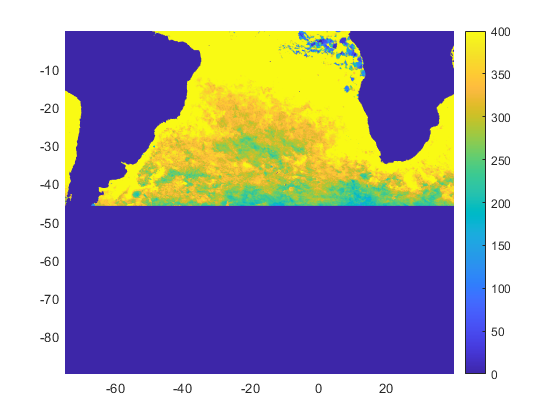

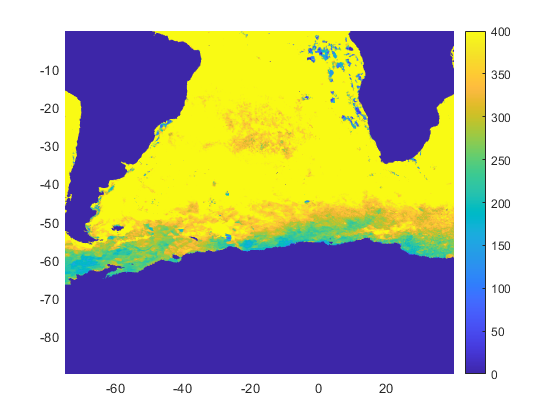

SR_line =   Line with properties:

              Color: [0.8000 0.4000 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1699 double]
              YData: [1×1699 double]
              ZData: [1×0 double]

  Show all properties


O_line =   Line with properties:

              Color: [0.6000 0.2000 0.8000]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×2871 double]
              YData: [1×2871 double]
              ZData: [1×0 double]

  Show all properties


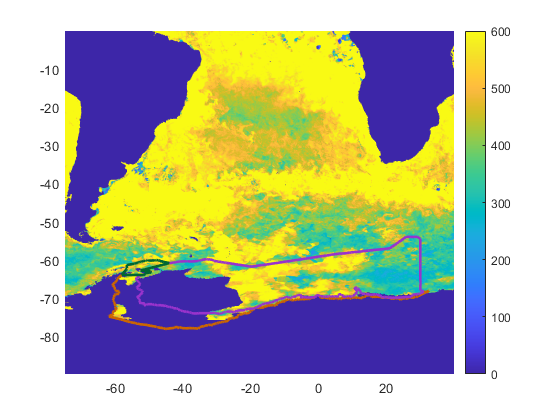

WAP_line =   Line with properties:

              Color: [0 0.4000 0.2000]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×449 double]
              YData: [1×449 double]
              ZData: [1×0 double]

  Show all properties


    if setup.checkregions
        ShelfBox=ShelfMinusWAPJan22;%shelf_region_ANDbox
        OOBox=OpenOceanMinusWAPJan22;%open_ocean_ANDbox
        WAPBox=WAPJan22;
        figure;
        pcolor(lon_wg,lat_wg,cafe_npp_all_8day(:,:,1)); shading flat; caxis([0 400]); colorbar;
        figure;
        pcolor(lon_wg,lat_wg,cafe_npp_all_8day(:,:,10)); shading flat; caxis([0 400]); colorbar;
        figure;
        pcolor(lon_wg,lat_wg,cafe_npp_all_8day(:,:,30)); shading flat; caxis([0 600]); colorbar;
        hold on
        SR_line=plot(ShelfBox(:,1),ShelfBox(:,2),'color',[0.8 0.4 0],'linewi',2)%'#80471C'
        O_line=plot(OOBox(:,1),OOBox(:,2),'color',[0.6 0.2 0.8],'linewi',2)%,'LineStyle','--')
        WAP_line=plot(WAPBox(:,1),WAPBox(:,2),'color',[0 0.4 0.2],'linewi',2)%,'LineStyle','--')
    end
    clearvars SR_line O_line

## Import regions: shelf and open ocean then andrex box

    BoxIn=andrex_box;
    %BoxIn=[-55,-55,-30,-30;-45,-38,-38,-45]'; % example input for a 4 corner box region
    ShelfBox=ShelfMinusWAPJan22;%shelf_region_ANDbox
    OOBox=OpenOceanMinusWAPJan22;%open_ocean_ANDbox
    WAPBox=WAPJan22;
    IN_and=inpolygon(lon_wg,lat_wg,BoxIn(:,1),BoxIn(:,2));
    findweddell=find(IN_and==1);
    IN_shelf=inpolygon(lon_wg,lat_wg,ShelfBox(:,1),ShelfBox(:,2));
    findshelf=find(IN_shelf==1);
    IN_open=inpolygon(lon_wg,lat_wg,OOBox(:,1),OOBox(:,2));
    findopen=find(IN_open==1);
    IN_wap=inpolygon(lon_wg,lat_wg,WAPBox(:,1),WAPBox(:,2));
    findWAP=find(IN_wap==1);
    
    region_sublist={'Weddell','Shelf','Open','AP'};
    regionfindlist= {'findweddell','findshelf','findopen','findWAP'};
    
    if setup.checkregions
        % % To check regions are within the same place
        for rix = 1:length(region_sublist)
            eval(['box_check.',region_sublist{rix},'=lat_wg;']);
            eval(['box_check.',region_sublist{rix},'(:)=0;']);
            eval(['box_check.',region_sublist{rix},'(',regionfindlist{rix},')=1;']);
            eval(['box_logic_check.',region_sublist{rix},'=logical(box_check.',region_sublist{rix},');']);
        end
        figure;
        pcolor(lon_wg,lat_wg,box_check.Weddell);
        shading flat
        figure;
        pcolor(lon_wg,lat_wg,box_check.Shelf);
        shading flat
        figure;
        pcolor(lon_wg,lat_wg,box_check.Open);
        shading flat
        hold on
        SR_line=plot(ShelfBox(:,1),ShelfBox(:,2),'color',[0.8 0.4 0],'linewi',2)%'#80471C'
        O_line=plot(OOBox(:,1),OOBox(:,2),'color',[0.6 0.2 0.8],'linewi',2)%,'LineStyle','--')
        WAP_line=plot(WAPBox(:,1),WAPBox(:,2),'color',[0 0.4 0.2],'linewi',2)%,'LineStyle','--')
        % they look correct now! Phew!!
    end
    % close all

## loop for box,box logic, area calcs

(varible area of open ice-free water calculated)

    for aix = 1:length(algorithm)
        for tix=1:length(timedec8day)
            % make mask for ocean/area where NPP is recorded
            tempNPP=chl_all_8day(:,:,tix); %using mg m^-2 array for this
            findNPP=find(tempNPP>fill); %>=0
            NPPmask=zeros(1080,1380);
            NPPmask(findNPP)=1;
            for rix = 1:length(region_sublist)
                %box,box logic
                temp.(region_sublist{rix}).box = lat_wg;
                temp.(region_sublist{rix}).box(:) = 0;
                eval(['temp.',region_sublist{rix},'.box(',regionfindlist{rix},')=1;']);
                
                temp.(region_sublist{rix}).box_logic=logical(temp.(region_sublist{rix}).box);
                
                % Area of Open Ice-Free water (per month)
                %             eval(['temp.area_MODIS=area_MODIS',algorithm{aix},'_m2;']);
                %             OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(tix,1)=nansum(nansum((temp.NPPmask).*(temp.area_MODIS).*(temp.(region_sublist{rix}).box)));
                
                % where there is ocean * area in m2 * region box. then summed = total area that there is ocean for each 8 day period
                % (Eq.1)
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(tix,1)=sum(sum(NPPmask.*area_MODIS_m2_wg.*(temp.(region_sublist{rix}).box),'omitnan'),'omitnan');
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_km2=CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2/1e6;
            end
        end
    end

## Area of region and sub-region

Sum of the area of the pixels within each region box (eq.0)

    for rix = 1:length(region_sublist)
        CHL_8day.total_areakm2.(region_sublist{rix})=sum(sum(area_MODIS_km2_wg.*(temp.(region_sublist{rix}).box),'omitnan'),'omitnan');
        CHL_8day.total_aream2.(region_sublist{rix})=sum(sum(area_MODIS_m2_wg.*(temp.(region_sublist{rix}).box),'omitnan'),'omitnan');
    end
    CHL_8day.total_areakm2.SROOtotal=CHL_8day.total_areakm2.Shelf+CHL_8day.total_areakm2.Open;
    CHL_8day.total_areakm2.SROOtot_WGdiff=CHL_8day.total_areakm2.SROOtotal-CHL_8day.total_areakm2.Weddell;
    %     clear IN_and IN_shelf IN_open tempNPP findNPP* NPPmask regionfindlist findweddell findshelf findopen

## Calculating variables

OceanProd_8day.total_area.(region_sublist{rix})

- (0) Total area of each region/sub-region (km2) $=A$

OceanProd_8day."algorithm"."region".

- (1) area_8day_m2 and area_8day_km2 = area of water visible to OC satellite/area of water where data is recorded (m^2 or km^2)


$$A_n =\int_{\Omega_n } \textrm{dA}$$


where $\Omega_n$ (a subset of the region $\Omega$) is defined by where $n$>0

- (2) NPP_tot_gc and NPP_tot_TgC = total C uptake (NPPtot) during each entry/time slices within each region (gC)


$$N_{\textrm{tot}} =\int_{t_i }^{t_{i+1} } \int_A n\;\textrm{dAdt}$$


- (3) Mean Chl across pixels where production is happening for each region/where pixels are visible (*note: Arrigo et al., 2008 PP in SO: "ice-covered regions are not included in calculations of either mean or time-integrated PP"). ($\textrm{mg}\;m^{-3} \;d^{-1}$)


$${\bar{c} }_c^A =\frac{\int_{\Omega_c } c\;\textrm{dA}}{\int_{\Omega_c } \textrm{dA}}$$


- (4) NPP_av_mgm2_zeros = mean daily NPP across entire area of region ($\textrm{mg}\;m^{-2} \;d^{-1}$)


$${\bar{n} }^A =\frac{\int_{\Omega } n\;\textrm{dA}}{\int_{\Omega } \textrm{dA}}$$


### Annual primary production:

- (5) NPP_tot_TgC_annual = **total C uptake over an austral year (TgC)**


$$N_{\textrm{tot}} =\int_{t_i }^{t_{i+1} } \int_A n\;\textrm{dAdt}$$


- (6) annual_rate_map= **annual rate of carbon production/area normalised productivity over a year?**

for each timestep: $n_{\textrm{norm}} =\frac{\int_{t_i }^{t_{i+1} } \int_A n\;\textrm{dAdt}}{\int_A \textrm{dA}}$

then integrate for whole year$=\int_{t_{\textrm{yr}\;\textrm{start}} }^{t_{\textrm{yr}\;\textrm{end}} } n_{\textrm{norm}} \;\textrm{dt}$

- (7) annual_areanorm= **area normalised productivity over a year and entire region ("productive and non-productive" a la Moore and Abbott, 2000)**


$${\bar{n} }_N^A =\frac{N_{\textrm{tot}} }{A_{\Omega } }$$


- (8) GSav_dayrate = the **mean daily rate** seen over the entire **growing season** (months and pixels where no data recorded are not included in this mean)


$${\bar{n} }_n^A =\frac{\int_{\Omega_n } n\;\textrm{dA}}{\int_{\Omega_n } \textrm{dA}}$$



$${\bar{n} }_n^{\textrm{At}} =\frac{\int_{t_{\textrm{yr}\;\textrm{start}} }^{t_{\textrm{yr}\;\textrm{end}} } {\bar{n} }_n^A \;\textrm{dt}}{\int_{t_{\textrm{yr}\;\textrm{start}} }^{t_{\textrm{yr}\;\textrm{end}} } \textrm{dt}}$$


- (9?) days_ice_free = approximate estimate of the number of days each region is ice free (where NPP>0) ... maybe the maximum days that any of the region is ice free?

???  


$$t_n =\int_{\Omega_n } \textrm{dt}$$



$${\bar{t} }^{\Omega } =\;$$



$$\sum d*\;\textrm{entries}\;\textrm{where}\;\textrm{NPPday}>0\;$$


???

where d is the number of days in a time slice - therefore, this is the maximum number of ice free days, because some of the days in the 8 day slices *could* have been ice covered...

See lines 80-104 of PixelAnalysis for mapped calculation of ice free days

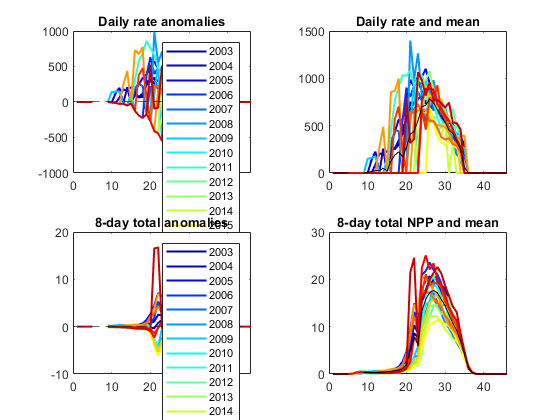

    for yix = 2003:2020
        findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
        chl_annualMEAN(:,:,yix-2002)=mean(chl_all_8day(:,:,findyear),3,'omitnan');
    end
    
    figure; tiledlayout('flow')
    for yix = 2003:2020
        nexttile
        pcolor(lon_wg,lat_wg,chl_annualMEAN(:,:,yix-2002)); shading flat
        caxis([0 2]); colorbar
        colormap(cmocean('algae',100))
        title(yix)
        xlim([-70 35]); ylim([-80 -50])
    end
    
    for rix = 1:length(region_sublist)
        for tix=1:length(timedec8day)
            % Mean Chl per 8-day period
            temp.chl=chl_all_8day(:,:,tix);
            temp.chlm22=temp.chl.*area_MODIS_m2_wg;
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_8day(tix,1)=...
                sum(sum(temp.chlm22(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_8day(tix,1)=...
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_8day(tix,1)...
                /CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(tix,1);
        end
    end
    
datenum_start=datenum(time_start_all);
datenum_end=datenum(time_end_all);
datenum_mid=mean([datenum_start,datenum_end],2);
datetime_mid=datetime(datenum_mid,'ConvertFrom','datenum');
    
%         for yix=2003:2020
%             temp.chlAn=chl_annualMEAN(:,:,yix-2002);
%             temp.chlAnm22=temp.chlAn.*area_MODIS_m2_wg;
%             CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_annual(yix-2002,1)=...
%                 mean(mean(temp.chlAnm22(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
%             CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_annual(yix-2002,1)=...
%                 CHL_8day.(algorithm{aix}).(region_sublist{rix}).meanCHL_annual(yix-2002,1)...
%                 /CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(tix,1);
%                 %NOT THE RIGHT AREA - need area of open water in the mean maps
%         end
    
    
    % nope - need to do area * chl for each time step, then 
    for aix = 1:length(algorithm)
        for yix=2003:2020
            % make mask for ocean/area where NPP is recorded each year
            tempNPP=chl_all_8day(:,:,tix); %using mg m^-2 array for this
            findNPP=find(tempNPP>fill); %>=0
            NPPmask=zeros(1080,1380);
            NPPmask(findNPP)=1;
            for rix = 1:length(region_sublist)
                %box,box logic
                temp.(region_sublist{rix}).box = lat_wg;
                temp.(region_sublist{rix}).box(:) = 0;
                eval(['temp.',region_sublist{rix},'.box(',regionfindlist{rix},')=1;']);
                
                temp.(region_sublist{rix}).box_logic=logical(temp.(region_sublist{rix}).box);
                
                % Area of Open Ice-Free water (per month)
                %             eval(['temp.area_MODIS=area_MODIS',algorithm{aix},'_m2;']);
                %             OceanProd.(algorithm{aix}).(region_sublist{rix}).area_month_m2(tix,1)=nansum(nansum((temp.NPPmask).*(temp.area_MODIS).*(temp.(region_sublist{rix}).box)));
                
                % where there is ocean * area in m2 * region box. then summed = total area that there is ocean for each 8 day period
                % (Eq.1)
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(tix,1)=sum(sum(NPPmask.*area_MODIS_m2_wg.*(temp.(region_sublist{rix}).box),'omitnan'),'omitnan');
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_km2=CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2/1e6;
            end
        end
    end
    
    
    
    
    % NPP 8-day timeseries
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for tix=1:length(timedec8day)
                % Total NPP per 8-day period
                temp.NPP_tot=NaN(1080,1380);
                eval(['temp.NPP(:,:)=',algorithm{aix},'_npp_tot_gC_nans_8day(:,:,tix);']);
                %                 temp.NPP=cafe_npp_all_8day(:,:,tix); %using mg m^-2 array for this
                
                % temp.NPP is total NPP in 8 day period (land/ice/clouds=Nan)
                %summed for pixels within region (eq.2)
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC(tix,1)=sum(sum(temp.NPP(temp.(region_sublist{rix}).box_logic),'omitnan'),'omitnan');
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_gC/1e12;
                
                % Mean daily rates for each 8-day period (eq.3)
                temp.NPP_daily=ones(1080,1380);
                eval(['temp.NPP_daily(:,:)=',algorithm{aix},'_npp_all_8day(:,:,tix);']);
                temp.findneg=find(temp.NPP_daily<0);
                temp.NPP_daily(temp.findneg)=NaN;
                temp.NPP_mgperday=temp.NPP_daily.*area_MODIScafe_m2_wg; % to get mean, need to bear in mind the different areas of pixels

                temp.NPP_daily_tot=sum(...
                    (temp.NPP_mgperday(temp.(region_sublist{rix}).box_logic)),...
                    [2 1],'omitnan');
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_nans(tix,1)=temp.NPP_daily_tot/CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(tix,1);
                % replace NaN estimates for 8 day period with zeros
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_nans;
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2(isnan(CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2))=0;
                
                %                 % mean daily rates for region for each 8-day period where ice covered is 0 (eq.4)
                %                 temp.NPP_daily(temp.findneg)=0;
                %                 OceanProd_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_zeros(tix,1)=mean(mean(temp.NPP_daily(temp.(region_sublist{rix}).box_logic)));
            end
        end
    end
    clearvars cafe_npp_tot_gC_nans_8day
    
    % Monthly means and anomalies
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for yix = 2003:2021
                if yix==2021
                    findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
                    tempytemp=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2(findyear);
                    tempytemp3=cat(1,tempytemp(1:5),NaN,NaN,NaN,tempytemp(6:end));
                    tempytemp2=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC(findyear);
                    tempytemp4=cat(1,tempytemp2(1:5),NaN,NaN,NaN,tempytemp2(6:end));
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_cols(:,yix-2002)=tempytemp3;
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_cols(:,yix-2002)=tempytemp4;
                else
                    findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_cols(:,yix-2002)=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2(findyear);
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_cols(:,yix-2002)=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC(findyear);
                end
            end
            clearvars tempytemp*
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_mean=mean(CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_cols,2);
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_anom=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_cols-CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_mean;
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_mean=mean(CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_cols,2);
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_anom=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_cols-CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_mean;
        end
    end
    
    if setup.plotfigures
        linecolors = jet(length(setup.yearrange0320));
        figure;
        tiledlayout('flow')
        nexttile
        for cix=1:length(setup.yearrange0320)
            plot(CHL_8day.cafe.Shelf.NPP_av_mgm2_anom(:,cix),'Color',linecolors(cix,:),'LineWidth',1.5);
            hold on
        end
        legend(num2str(setup.yearrange0320))
        yline(0,'--')
        title('Daily rate anomalies')
        nexttile
        for cix=1:length(setup.yearrange0320)
            plot(CHL_8day.cafe.Shelf.NPP_av_mgm2_cols(:,cix),'Color',linecolors(cix,:),'LineWidth',1.5);
            hold on
            plot(CHL_8day.cafe.Shelf.NPP_av_mgm2_mean,'k');
        end
        title('Daily rate and mean')
        nexttile
        for cix=1:length(setup.yearrange0320)
            plot(CHL_8day.cafe.Weddell.NPP_tot_TgC_anom(:,cix),'Color',linecolors(cix,:),'LineWidth',1.5);
            hold on
        end
        legend(num2str(setup.yearrange0320))
        yline(0,'--')
        title('8-day total anomalies')
        nexttile
        for cix=1:length(setup.yearrange0320)
            plot(CHL_8day.cafe.Weddell.NPP_tot_TgC_cols(:,cix),'Color',linecolors(cix,:),'LineWidth',1.5);
            hold on
            plot(CHL_8day.cafe.Weddell.NPP_tot_TgC_mean,'k');
        end
        title('8-day total NPP and mean')
    end
    
    % Annual total NPP (eq.5), annual open water variables
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for yix = 2002:2021
                findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
                
                % Integrated NPP over austral year (July to June)
                % and total and mean annual open ice-free water area and max monthly
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,1)=yix;
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,1)=yix;
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,1)=yix;
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,1)=yix;
                
                if size(findyear)<43
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)=NaN;
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)=NaN;
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,2)=NaN;
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,2)=NaN;
                else
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(yix-2001,2)=sum(CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC(findyear,1));
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)=sum(CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_km2(findyear));
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMEAN(yix-2001,2)=CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualTOT(yix-2001,2)/46;
                    CHL_8day.(algorithm{aix}).(region_sublist{rix}).IceFree_annualMAX(yix-2001,2)=max(CHL_8day.(algorithm{aix}).(region_sublist{rix}).area_8day_m2(findyear,1),[],'omitnan');
                end
            end
        end
    end
    
    % Annual rates of NPP (mg C m^-2 yr^-1) (eq.6)
    for rix = 1:length(region_sublist)
        CHL_8day.cafe.(region_sublist{rix}).areanorm_timestep=(CHL_8day.cafe.(region_sublist{rix}).NPP_tot_gC./...
            CHL_8day.cafe.(region_sublist{rix}).area_8day_m2); % total prod in a time slice divided by the area of the region during that time slice
        for yix = 2003:2021
            findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
            CHL_8day.cafe.(region_sublist{rix}).AnnualNPPRate_gm2peryear(yix-2002,1)=sum(CHL_8day.cafe.(region_sublist{rix}).areanorm_timestep(findyear),'omitnan');
        end
    end
    
    %Area normalised NPP (?) (eq.7) - normalised to arbirtary region
    %boundaries, as opposed to the actual area of ocean that was productive
    %(i.e. use eq 6)
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).AreaNormNPP=(...
                (CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(:,2)*1e12)./...
                (CHL_8day.total_areakm2.(region_sublist{rix})*1e6));
        end
    end
    
    % Mean daily rate each year (eq.8)
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for yix = 2003:2021
                clearvars temp1 temp2
                findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
                tempNPP_year=CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_av_mgm2_nans(findyear);
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).AnAvDayRate_mgm2d1(yix-2002,1)=...
                    mean(tempNPP_year,"omitnan");
            end
        end
    end
    clearvars temp_anntot tempNPP_yeararray findyear
    
    % Ice free days (eq.?9)
    leapyear1=time_start_all(:,1);
    leapyear2=rem(leapyear1,4)==0;
    leapyear3=zeros(length(leapyear1),1);
    leapyear3(leapyear2==1)=366;
    leapyear3(leapyear3==0)=365;
    days_test(:,1)=(timedec8day_end-timedec8day);
    days_test(:,2)=days_test(:,1)*365;
    days_test(:,3)=days_test(:,1).*leapyear3;
    day_chunk=round(days_test(:,1).*leapyear3);
    
    IceFreeDays_peryear=NaN(1080,1380,length([2003:1:2021]));
    for yix = 2003:2021
        temp4=zeros(1080,1380);
        findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
        tempNPP_yeararray=cafe_npp_all_8day(:,:,findyear); %austral year time slice of NPP av daily rates
        temp_daychunk=day_chunk(findyear);
        daystot=sum(temp_daychunk);
        %         if round(daystot)<365 % havent thought of a work around for 2021 yet
        %             error('days tot less than a year')
        %         end
        for qix=1:1:length(findyear)
            temparray=tempNPP_yeararray(:,:,qix); % one by one, go through 8 day slices for each aus year
            temp2=ones(size(temparray)); % make blank array
            temp2(find(temparray<0))=0; % put in 1s where there is data and zeros where there is no data
            temp3=temp2*temp_daychunk(qix); % multiply 1s (data present) by the number of days in the time slice = number of days ice free
            temp4=temp4+temp3; % total number of days Ice Free
        end
        IceFreeDays_peryear(:,:,yix-2002)=temp4;%.*area_MODIScafe_m2_wg; % weight ice free days by area of pixel
    end
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            for yix = 2003:2021
                temparray=IceFreeDays_peryear(:,:,yix-2002);
                
                templogic=zeros(size(temparray));
                templogic(temparray>0)=1; % where there were ice free days, set to 1
                temparea=templogic.*area_MODIScafe_m2_wg; % array of areas where there were ice free days
                
                temp_totarea(yix-2002,1)=sum(temparea(temp.(region_sublist{rix}).box_logic),'omitnan'); %total area where there were ice free days
                temp_IFDsum(yix-2002,1)=sum(temparray(temp.(region_sublist{rix}).box_logic),'omitnan'); %total
                
                tt=(temparray./area_MODIScafe_m2_wg);
                temp_IFDmean(yix-2002,1)=mean(tt(temp.(region_sublist{rix}).box_logic),'omitnan');
                
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).IFD_av(yix-2002,1)=...
                    temp_IFDsum(yix-2002,1)/temp_totarea(yix-2002,1);
                CHL_8day.(algorithm{aix}).(region_sublist{rix}).IFD_max(yix-2002,1)=...
                    max(tt(temp.(region_sublist{rix}).box_logic),[],[2 1]);
            end
        end
    end
    clearvars temp2 temp3 temp4 tempNPP_yeararray temp_daychunk daystot temparray templogic temparea temp_totarea temp_IFD*
    
    % mean annual total NPP and ice-free water area
    for aix = 1:length(algorithm)
        for rix = 1:length(region_sublist)
            CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_MEANtot_TgC_annual=mean(CHL_8day.(algorithm{aix}).(region_sublist{rix}).NPP_tot_TgC_annual(:,2),'omitnan');
        end
    end
    
    % proportion of ice-free area seen in OO & SR
    for aix = 1:length(algorithm)
        CHL_8day.(algorithm{aix}).(region_sublist{2}).IceFree_proportion(:,1)=(CHL_8day.(algorithm{aix}).(region_sublist{2}).IceFree_annualMEAN(:,2)./CHL_8day.(algorithm{aix}).(region_sublist{1}).IceFree_annualMEAN(:,2)).*100;
        CHL_8day.(algorithm{aix}).(region_sublist{2}).IceFree_AVproportion=nanmean(CHL_8day.(algorithm{aix}).(region_sublist{2}).IceFree_proportion(:,1));
        CHL_8day.(algorithm{aix}).(region_sublist{3}).IceFree_proportion(:,1)=(CHL_8day.(algorithm{aix}).(region_sublist{3}).IceFree_annualMEAN(:,2)./CHL_8day.(algorithm{aix}).(region_sublist{1}).IceFree_annualMEAN(:,2)).*100;
        CHL_8day.(algorithm{aix}).(region_sublist{3}).IceFree_AVproportion=nanmean(CHL_8day.(algorithm{aix}).(region_sublist{3}).IceFree_proportion(:,1));
    end
    
    
    %% Annual rate map
    AnnualNPPRate_mgperyear=NaN(1080,1380,length([2003:1:2020]));
    for yix = 2003:2021
        clearvars temp1 temp2
        temp_anntot=zeros(1080,1380);
        findyear=find(timedec8day>yix-0.5 & timedec8day<yix+0.5);
        tempNPP_yeararray=cafe_npp_all_8day(:,:,findyear); %austral year time slice of NPP av daily rates
        tempNPP_yeararray(tempNPP_yeararray<0)=NaN;
        temp_daychunk=day_chunk(findyear);
        
        for qix=1:1:length(findyear)
            temparray=tempNPP_yeararray(:,:,qix); % one by one, go through 8 day slices for each aus year
            temp2=temparray*temp_daychunk(qix);
            temp2(isnan(temp2))=0;
            temp_anntot=temp_anntot+temp2;
        end
        AnnualNPPRate_mgperyear(:,:,yix-2002)=temp_anntot;
    end
    
    AnnualNPPRate_mgperyear(AnnualNPPRate_mgperyear==0)=NaN;
    AnnualNPPRate_gperyear=AnnualNPPRate_mgperyear./1000;
end

%     clearvars regionfindlist findweddell findshelf findopen temp setup
save('ProcessedData_8day_May22.mat','CHL_8day','algorithm','region_sublist','timedec8day','time_start_all','time_end_all');
save('ProcessedCAFEArrays_May22.mat','AnnualNPPRate_gperyear','IceFreeDays_peryear','region_sublist','timedec8day','lat_wg','lon_wg'); %,'AnAvDayRate_mgm2d1' ??
% clearvars -except OceanProd* algorithm region_sublist time* cafe_npp_all time* lat_* lon_* andrex_box